**Ex 2**

clc
clear
load('Ex4-data')


(1)

fprintf('G1:')

G1:

fprintf('number of states = %1.0f', size(get(G1, 'A'), 1));

number of states = 4

fprintf('number of inputs = %1.0f', size(get(G1, 'B'), 2));

number of inputs = 1

fprintf('number of outputs = %1.0f', size(get(G1, 'C'), 1));

number of outputs = 1


fprintf('G2:')

G2:

fprintf('number of states = %1.0f', size(get(G2, 'A'), 1));

number of states = 4

fprintf('number of inputs = %1.0f', size(get(G2, 'B'), 2));

number of inputs = 1

fprintf('number of outputs = %1.0f', size(get(G2, 'C'), 1));

number of outputs = 1

(2)

for discret system, all eigenvalue needs to be in the unit circle so we check this on system G1 and G2. That's the eigen value of the matrix A.

eigen_value1 = eig(G1)

eigen_value1 =     0.9800
    0.4000
    0.2000
    0.1500


eigen_value_bis1 = eig(get(G1, 'A'))

eigen_value_bis1 =     0.9800
    0.4000
    0.2000
    0.1500



if all(abs(eigen_value1) < 1)
    fprintf('The system G1 is stable.\n');
else
    fprintf('The system is G1 unstable.\n');
end

The system G1 is stable.



eigen_value2 = eig(G2)

eigen_value2 =    -0.1000
    0.3000
    0.8500
    0.9000


eigen_value_bis2 = eig(get(G2, 'A'))

eigen_value_bis2 =    -0.1000
    0.3000
    0.8500
    0.9000



if all(abs(eigen_value2) < 1)
    fprintf('The system G2 is stable.\n');
else
    fprintf('The system is G2 unstable.\n');
end

The system G2 is stable.


(3)

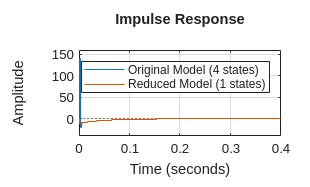

%% Reduce LTI model order using modal truncation
 
% Compute modal decomposition and select modes
R = reducespec(G1,'modal');
% Compute MOR data once
R = process(R);
% Get reduced-order model
G1DP = getrom(R,Frequency=[0.001 338.1],MinDC=0.401173228346459,Method='truncate');
 
% Create comparison plot
f = figure();
h = impulseplot(f,G1,G1DP);
legend(h,['Original Model (',mat2str(order(G1)),' states)'],...
         ['Reduced Model (',mat2str(order(G1DP)),' states)']);
h.AxesStyle.GridVisible = true;

 
 
% Remove temporary variables from Workspace
clear R f h


(4)

fprintf('eigenvalue of the reduced-order system: %f', eig(G1DP))

eigenvalue of the reduced-order system: 0.980000

(5)

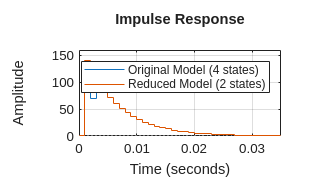

%% Reduce LTI model order using modal truncation
 
% Compute modal decomposition and select modes
R2 = reducespec(G2,'modal');
% Compute MOR data once
R2 = process(R2);
% Get reduced-order model
G2DP = getrom(R2,Frequency=[0.001 338.1],MinDC=0.119260465116278,Method='truncate');
 
% Create comparison plot
f2 = figure();
h2 = impulseplot(f2,G2,G2DP);
legend(h2,['Original Model (',mat2str(order(G2)),' states)'],...
         ['Reduced Model (',mat2str(order(G2DP)),' states)']);
h2.AxesStyle.GridVisible = true;

 
 
% Remove temporary variables from Workspace
clear R2 f2 h2

(7)

Co = ctrb(G1.A, G1.B);
if length(G1.A)-rank(Co) == 0
    fprintf('G1 is controllable.');
else
    fprintf('G1 is not controllable.');
end

G1 is controllable.


Ob = obsv(G1.A, G1.C);
if length(G1.A)-rank(Ob) == 0
    fprintf('G1 is observable.');
else
    fprintf('G1 is not observable.');
end

G1 is observable.


Co = ctrb(G2.A, G2.B);
if length(G2.A)-rank(Co) == 0
    fprintf('G2 is controllable.');
else
    fprintf('G2 is not controllable.');
end

G2 is controllable.


Ob = obsv(G2.A, G2.C);
if length(G2.A)-rank(Ob) == 0
    fprintf('G2 is observable.');
else
    fprintf('G2 is not observable.');
end

G2 is observable.

(8)